%% ex5_homoclinic_bifurcation_euler.m
% Homoclinic bifurcation demo using a fixed-step Forward Euler integrator.
%
% WHY Euler here?
%   Near homoclinic bifurcations the period can become very large, and
%   adaptive solvers (ode45) may take a long time due to tight error control.
%   Forward Euler with a controlled dt gives predictable compute cost.
%
% Model (given):
%   x' = y
%   y' = mu*y + x - x^2 + x*y
%
% Interpretation:
%   - (0,0) is a saddle for all mu.
%   - (1,0) undergoes a Hopf at mu = -1 (trace = mu+1).
%   - A stable limit cycle (born near Hopf) grows and (numerically)
%     approaches a homoclinic orbit to the saddle as mu -> mu_c^-.
%   - Instructor-provided homoclinic parameter estimate:
%         mu_c \approx -0.8645
%
% Outputs:
%   (A) Phase portrait at a representative mu < mu_c (vector field + nullclines
%       + trajectories).
%   (B) Estimated limit-cycle period and amplitude versus "distance"
%       delta = mu_c - mu > 0.
%
% Notes on numerical accuracy:
%   Euler is first-order; period/amplitude estimates are qualitative.
%   If you want more accuracy without ode45 cost, switch to RK2/RK4.
%
% Author: (generated)

clear; close all; clc;

%% ---------------------- User-controlled settings ----------------------
mu_c   = -0.8645;          % homoclinic parameter (given)
mu_demo = mu_c + -0.05;     % representative parameter where a limit cycle exists

% Euler step size: smaller -> more accurate, more cost.
dt     = 1e-3;

% Maximum integration time per run.
% Near homoclinic, periods can be large; increase Tmax if you want smaller deltas.
Tmax   = 600;

% For period estimation: count downward zero-crossings of y (maxima of x).
% We discard early peaks as transient.
peaks_discard = 2;
peaks_needed  = 6;   % total peaks needed to estimate period (after transient)

% Initial condition for attracting cycle (typically):
x0 = 1.2;
y0 = 0.0;

% Phase plane plotting window
xwin = [-1.5, 2.2];
ywin = [-1.5, 1.5];

%% ---------------------- (A) Phase portrait demo ----------------------
figure('Name','Homoclinic: phase plane (Euler trajectories)');

% Vector field grid
Nx = 25; Ny = 25;
[xg, yg] = meshgrid(linspace(xwin(1),xwin(2),Nx), linspace(ywin(1),ywin(2),Ny));
[dxg, dyg] = vf(xg, yg, mu_demo);

% Normalize arrows for cleaner quiver
spd = sqrt(dxg.^2 + dyg.^2);
spd(spd==0) = 1;
quiver(xg, yg, dxg./spd, dyg./spd, 0.55);
hold on; box on;
xlabel('x'); ylabel('y');
title(sprintf('Phase portrait for \mu = %.4f (Euler dt=%.1e)', mu_demo, dt));

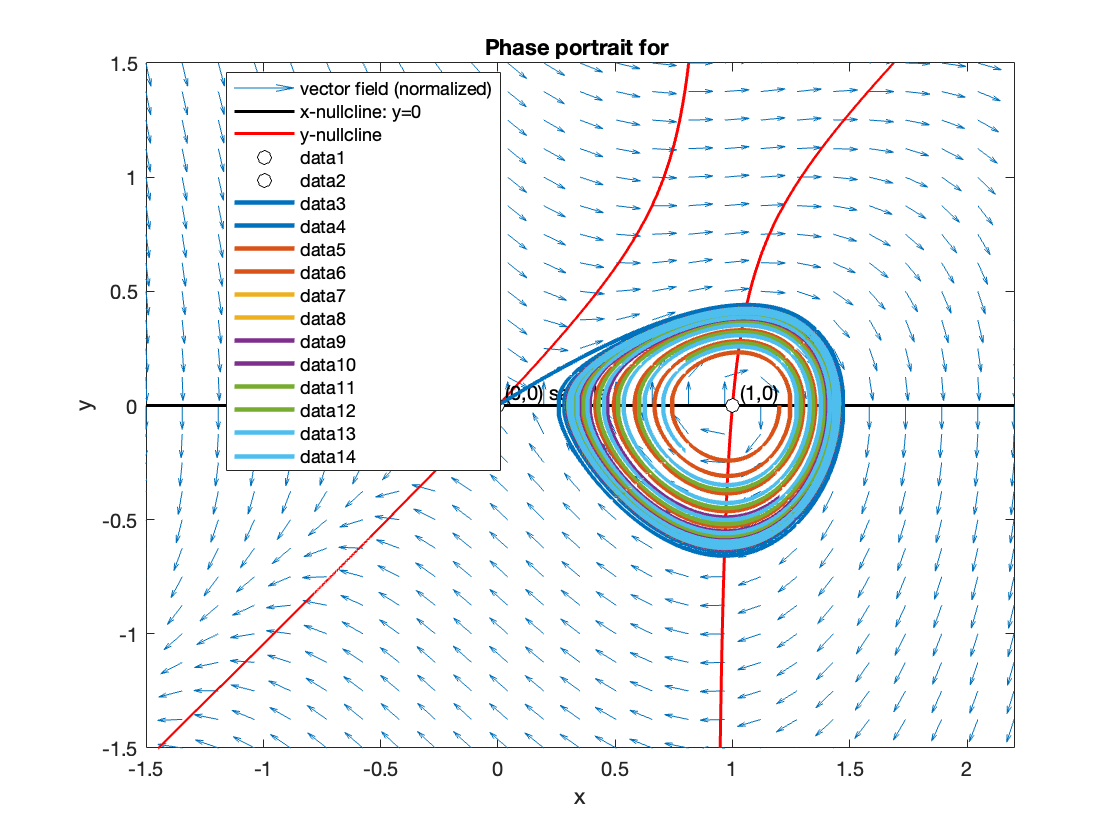


% Nullclines
% x-nullcline: x' = 0 -> y = 0
plot(xwin, [0 0], 'k-', 'LineWidth', 1.5);

% y-nullcline: y' = 0 -> (mu + x) y = x(x-1)
% i.e. y = x(x-1)/(mu+x), avoiding x=-mu.
xx = linspace(xwin(1), xwin(2), 1500);
denom = (mu_demo + xx);
mask = abs(denom) > 1e-3;  % avoid pole
ynull = nan(size(xx));
ynull(mask) = (xx(mask).*(xx(mask)-1))./denom(mask);
plot(xx, ynull, 'r-', 'LineWidth', 1.5);
legend({'vector field (normalized)','x-nullcline: y=0','y-nullcline'}, 'Location','best');

% Equilibria (always at y=0 and x-x^2=0 -> x=0,1)
plot(0,0,'ko','MarkerFaceColor','w','MarkerSize',7);
plot(1,0,'ko','MarkerFaceColor','w','MarkerSize',7);
text(0.03, 0.06, '(0,0) saddle');
text(1.03, 0.06, '(1,0)');

% Trajectories from a few initial conditions
ICs = [ 0.01 0.01;
        1.2  0.0;
        1.2  0.4;
        1.2 -0.4;
        0.8  0.2;
        0.8 -0.2];
colors = lines(size(ICs,1));

for i = 1:size(ICs,1)
    [t,x,y,peakInfo] = euler_run(mu_demo, dt, Tmax, ICs(i,1), ICs(i,2), peaks_discard, peaks_needed);
    plot(x, y, '-', 'LineWidth', 2.2, 'Color', colors(i,:));

    % Highlight last cycle segment if we detected peaks
    if peakInfo.ok
        idx1 = peakInfo.idx_peaks(end-1);
        idx2 = peakInfo.idx_peaks(end);
        plot(x(idx1:idx2), y(idx1:idx2), '-', 'LineWidth', 2.2, 'Color', colors(i,:));
    end
end

xlim(xwin); ylim(ywin);


%% ---------------------- (B) Period & amplitude vs delta --------------
% We approach mu_c from below: mu = mu_c - delta, delta>0.
% Choose deltas so that mu stays above -1 (where Hopf happens): mu>-1.

% You can tighten deltas for stronger divergence, but you may need larger Tmax.
deltas = [0.10 0.07 0.05 0.04 0.03 0.02 0.015 0.012 0.010];

mu_list = mu_c - deltas;
% Ensure we are in the regime where the limit cycle exists (typically mu>-1).
valid = mu_list > -0.999;  % keep a small safety margin
mu_list = mu_list(valid);
deltas  = deltas(valid);

T_est = nan(size(mu_list));
A_est = nan(size(mu_list));
status = strings(size(mu_list));

fprintf('--- Euler homoclinic demo ---\n');

--- Euler homoclinic demo ---


fprintf('mu_c = %.4f, dt = %.1e, Tmax = %.1f\n', mu_c, dt, Tmax);

mu_c = -0.8645, dt = 1.0e-03, Tmax = 600.0



for k = 1:numel(mu_list)
    mu = mu_list(k);
    [t,x,y,peakInfo] = euler_run(mu, dt, Tmax, x0, y0, peaks_discard, peaks_needed);
    if peakInfo.ok
        T_est(k) = peakInfo.period;
        A_est(k) = peakInfo.amp;
        status(k) = "ok";
    else
        status(k) = peakInfo.msg;
    end
    fprintf('mu = %.4f (delta=%.4f): %s\n', mu, deltas(k), status(k));
end

mu = -0.9645 (delta=0.1000): ok
mu = -0.9345 (delta=0.0700): ok
mu = -0.9145 (delta=0.0500): ok
mu = -0.9045 (delta=0.0400): ok
mu = -0.8945 (delta=0.0300): ok
mu = -0.8845 (delta=0.0200): ok
mu = -0.8795 (delta=0.0150): ok
mu = -0.8765 (delta=0.0120): ok
mu = -0.8745 (delta=0.0100): ok


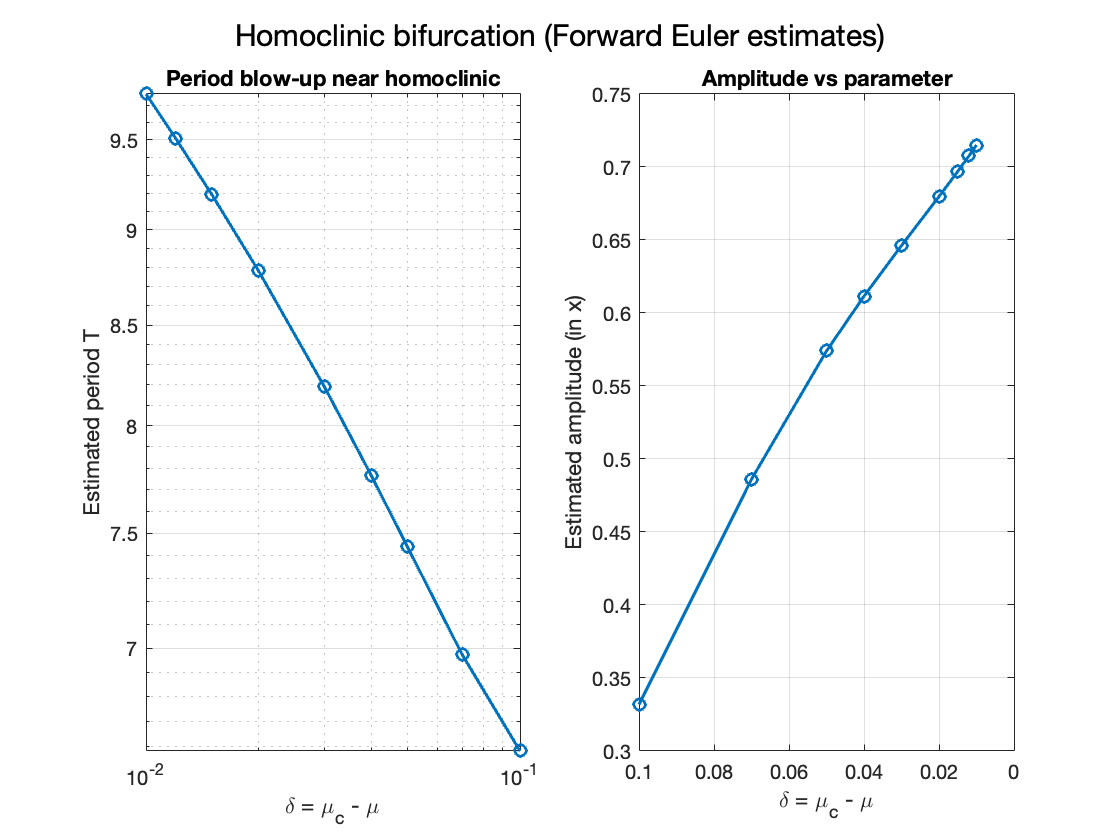


figure('Name','Homoclinic: period/amplitude vs distance');

subplot(1,2,1);
loglog(deltas, T_est, 'o-','LineWidth',1.5);
grid on;
xlabel('\delta = \mu_c - \mu');
ylabel('Estimated period T');
title('Period blow-up near homoclinic');

subplot(1,2,2);
plot(deltas, A_est, 'o-','LineWidth',1.5);
set(gca,'XDir','reverse'); % show approach to 0 on the right visually
grid on;
xlabel('\delta = \mu_c - \mu');
ylabel('Estimated amplitude (in x)');
title('Amplitude vs parameter');

sgtitle('Homoclinic bifurcation (Forward Euler estimates)');

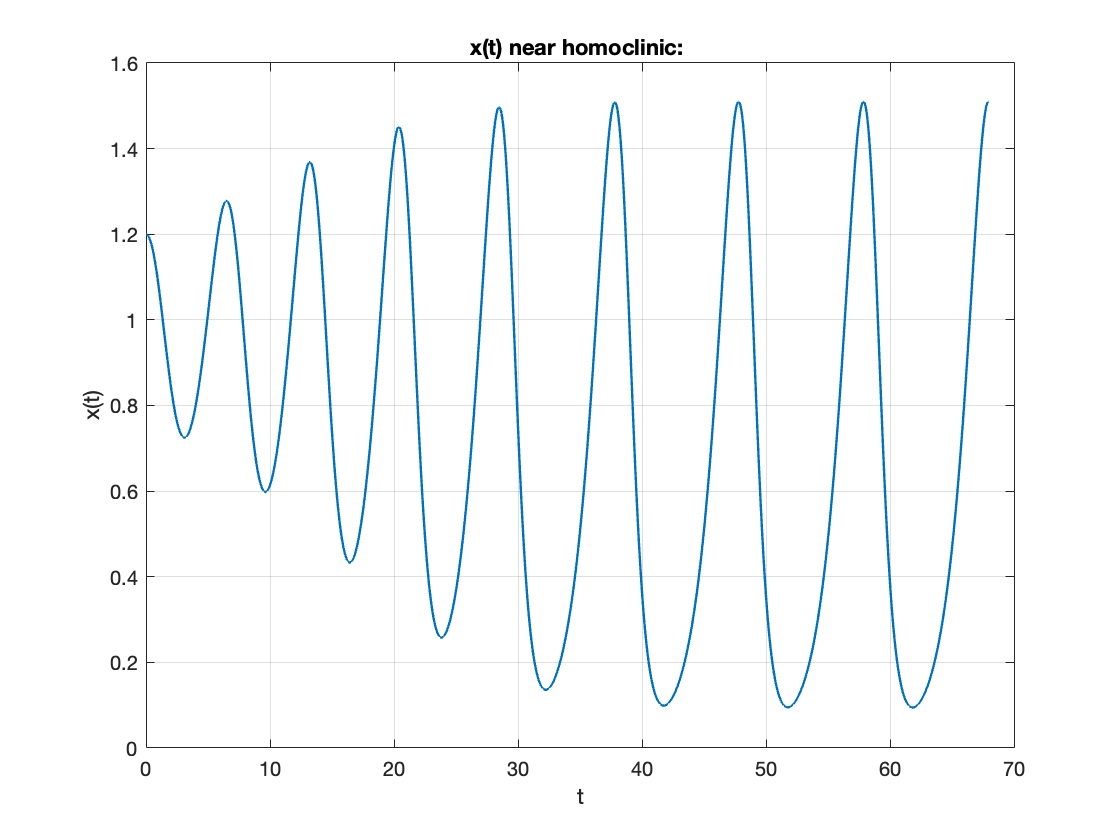


%% ---------------------- Optional: sample time series -----------------
% Show x(t) for a mu close to mu_c to visualize slowing.
mu_ts = mu_c - 0.012;
[t,x,y,peakInfo] = euler_run(mu_ts, dt, Tmax, x0, y0, peaks_discard, peaks_needed);

figure('Name','Homoclinic: time series near mu_c');
plot(t, x, 'LineWidth', 1.2);
grid on;
xlabel('t'); ylabel('x(t)');
title(sprintf('x(t) near homoclinic: \mu=%.4f (\delta=%.4f)', mu_ts, mu_c-mu_ts));



%% =====================================================================
% Local functions
% =====================================================================


function [dx,dy] = vf(x,y,mu)

mu = -0.9500

% Vector field for the planar system
%   x' = y
%   y' = mu*y + x - x^2 + x*y
    dx = y;
    dy = mu.*y + x - x.^2 + x.*y;
end

function [t,x,y,info] = euler_run(mu, dt, Tmax, x0, y0, discardPeaks, needPeaks)
% Forward Euler integration with peak detection.
% Peaks of x occur when y crosses 0 from + to - (since x' = y).

    Nmax = ceil(Tmax/dt);

    x = zeros(Nmax+1,1);
    y = zeros(Nmax+1,1);
    t = zeros(Nmax+1,1);
    x(1) = x0;
    y(1) = y0;

    peaki = zeros(needPeaks + discardPeaks + 5, 1); % indices of detected peaks
    peakCount = 0;

    for n = 1:Nmax
        % Euler step
        dx = y(n);
        dy = mu*y(n) + x(n) - x(n)^2 + x(n)*y(n);

        x(n+1) = x(n) + dt*dx;
        y(n+1) = y(n) + dt*dy;
        t(n+1) = t(n) + dt;

        % Detect a local maximum of x: y crosses from positive to nonpositive
        if (y(n) > 0) && (y(n+1) <= 0)
            peakCount = peakCount + 1;
            peaki(peakCount) = n+1;

            if peakCount >= (discardPeaks + needPeaks)
                % Enough peaks detected; stop early
                break;
            end
        end

        % Safety: if solution blows up, stop
        if ~isfinite(x(n+1)) || ~isfinite(y(n+1)) || abs(x(n+1))>1e3 || abs(y(n+1))>1e3
            info.ok = false;
            info.msg = "diverged";
            t = t(1:n+1); x = x(1:n+1); y = y(1:n+1);
            return;
        end
    end

    nStop = n+1;
    t = t(1:nStop);
    x = x(1:nStop);
    y = y(1:nStop);

    if peakCount < (discardPeaks + 3)
        info.ok = false;
        info.msg = "not enough peaks";
        return;
    end

    % Use peaks after transient
    idx_peaks = peaki(discardPeaks+1:peakCount);

    if numel(idx_peaks) < 3
        info.ok = false;
        info.msg = "not enough post-transient peaks";
        return;
    end

    % Period estimate: average over consecutive peak-to-peak times
    tp = t(idx_peaks);
    dT = diff(tp);
    info.period = mean(dT);

    % Amplitude estimate from last full cycle window
    i1 = idx_peaks(end-1);
    i2 = idx_peaks(end);
    xseg = x(i1:i2);
    info.amp = 0.5*(max(xseg) - min(xseg));

    info.ok = true;
    info.idx_peaks = idx_peaks;
    info.msg = "ok";
end
